[header, record] = load_EOG(4, 'R');

Step 1
Reading requested records. (This may take a few minutes.)...
R
Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


absrec = abs(record(1,:))

absrec =    11.2745   16.1765    8.3333    1.4706    2.4510   17.1569   35.7843   59.3137   50.4902   41.6667   26.9608   15.1961   22.0588   12.2549    4.4118   14.2157    8.3333   10.2941   15.1961   13.2353   10.2941    5.3922   53.4314   86.7647   90.6863   87.7451   82.8431   76.9608   67.1569   58.3333   50.4902   47.5490   47.5490   40.6863   34.8039   35.7843   46.5686   60.2941   61.2745   57.3529   51.4706   43.6275   43.6275   34.8039   33.8235   25.9804   22.0588   18.1373   12.2549   13.2353


Fs = header.samples / header.duration

Fs = 50

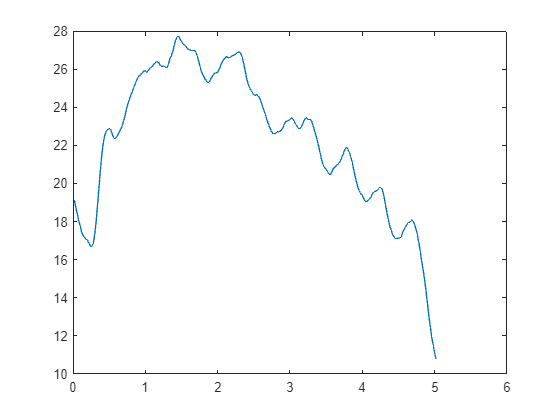

epoch_n = 1515;
epoch_len_s = 5;
epoch_len = epoch_len_s * Fs;
cutout = absrec(epoch_len * epoch_n:epoch_len * (epoch_n+1));
cutout = movmean(cutout, Fs*2);
plot((1:length(cutout))/Fs, cutout);